1. Write a matlab code for generating DCT bases for a sequence of length 17. Use Outer product concept. Also normalize the row vectors

N = 17; % length of the signal
k = zeros(N,1)

k =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


b = (0:N-1)*pi/N+pi/(2*N) % row vector

b =     0.0924    0.2772    0.4620    0.6468    0.8316    1.0164    1.2012    1.3860    1.5708    1.7556    1.9404    2.1252    2.3100    2.4948    2.6796    2.8644    3.0492


mul = (0:N-1)' % column vector

mul =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


D = cos(mul*b) % rowwise bases (D*D’=diagonal)

D =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9957    0.9618    0.8952    0.7980    0.6737    0.5264    0.3612    0.1837    0.0000   -0.1837   -0.3612   -0.5264   -0.6737   -0.7980   -0.8952   -0.9618   -0.9957
    0.9830    0.8502    0.6026    0.2737   -0.0923   -0.4457   -0.7390   -0.9325   -1.0000   -0.9325   -0.7390   -0.4457   -0.0923    0.2737    0.6026    0.8502    0.9830
    0.9618    0.6737    0.1837   -0.3612   -0.7980   -0.9957   -0.8952   -0.5264   -0.0000    0.5264    0.8952    0.9957    0.7980    0.3612   -0.1837   -0.6737   -0.9618
    0.9325    0.4457   -0.2737   -0.8502   -0.9830   -0.6026    0.0923    0.7390    1.0000    0.7390    0.0923   -0.6026   -0.9830   -0.8502   -0.2737    0.4457    0.9325
    0.8952    0.1837   -0.6737   -0.9957   -0.5264    0.3612    0.9618    0.7980    0.0000   -0.7980   -0.9618   -0.3612    0.5264    0.9957 

D = [D(1,:); D(2:end,:);] % rowwise normalized bases

D =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9957    0.9618    0.8952    0.7980    0.6737    0.5264    0.3612    0.1837    0.0000   -0.1837   -0.3612   -0.5264   -0.6737   -0.7980   -0.8952   -0.9618   -0.9957
    0.9830    0.8502    0.6026    0.2737   -0.0923   -0.4457   -0.7390   -0.9325   -1.0000   -0.9325   -0.7390   -0.4457   -0.0923    0.2737    0.6026    0.8502    0.9830
    0.9618    0.6737    0.1837   -0.3612   -0.7980   -0.9957   -0.8952   -0.5264   -0.0000    0.5264    0.8952    0.9957    0.7980    0.3612   -0.1837   -0.6737   -0.9618
    0.9325    0.4457   -0.2737   -0.8502   -0.9830   -0.6026    0.0923    0.7390    1.0000    0.7390    0.0923   -0.6026   -0.9830   -0.8502   -0.2737    0.4457    0.9325
    0.8952    0.1837   -0.6737   -0.9957   -0.5264    0.3612    0.9618    0.7980    0.0000   -0.7980   -0.9618   -0.3612    0.5264    0.9957 

D'*D % Identity matrix

ans =     9.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    9.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    9.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    9.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    9.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000    0.5000    9.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.500

 2. Create a random integer matrix of size 15x15 with rank 10

R=[0 9];
A=randi(R,15,10)*randi(R,10,15)

A =    201   136   257   133   283   229   201   210   139   190   125   266   253   163   286
   204   167   263   168   298   181   195   194   140   159   115   199   275   119   292
   202   179   318   220   327   200   220   189   206   188   170   242   332   208   336
   169   146   179   119   224   184   161   124   129   104   108   161   195   128   215
   177   142   272   172   265   180   198   235   141   180   174   261   266   207   281
   202   147   304   159   322   174   160   192   138   209   125   243   309   179   299
   191   133   257    85   237   153   147   228   109    83   173   206   273   212   231
   201   189   283   181   270   183   201   165   199   142   134   219   293   162   295
   206   139   311   128   323   202   180   255   166   242   142   329   312   214   333
   154   121   216   116   251   133   138   191   122   137   127   195   237   157   247


rank(A)

ans = 10

3. Generate data pair sequence from the equation

x=-10:0.1:10;
x=x';
yc=4*x+8;
noise = 1 + 2.*randn(201,1);
y=yc+noise;
A=[x ones(size(x))]

A =   -10.0000    1.0000
   -9.9000    1.0000
   -9.8000    1.0000
   -9.7000    1.0000
   -9.6000    1.0000
   -9.5000    1.0000
   -9.4000    1.0000
   -9.3000    1.0000
   -9.2000    1.0000
   -9.1000    1.0000


Z=inv(A'*A)*A'*y

Z =     3.9798
    9.1182


e=y-A*Z

e =    -0.5896
    3.2403
   -0.7955
    1.4015
   -2.0692
   -1.8343
    1.4172
    0.9902
    1.8118
   -1.5687


e'*A

ans = 	1.0e+-11 *

    0.8200    0.1060


m=Z(1);
c=Z(2);
yp=m*x+c

yp =   -30.6794
  -30.2815
  -29.8835
  -29.4855
  -29.0875
  -28.6896
  -28.2916
  -27.8936
  -27.4956
  -27.0977


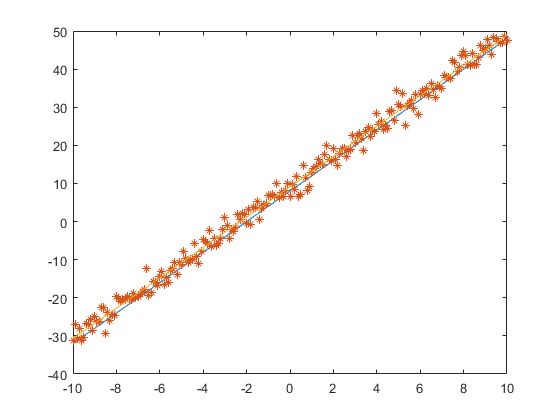

plot (x,yc)
hold on
plot(x,y,'*');
hold on
plot (x,yp)

4.Generate a 4x5 random matrix of rank 3.

A=randi(10,4,3)* randi(10,3,5); %generate 4x5 matrix with rank=3
B=nchoosek(1:5,3)

B =      1     2     3
     1     2     4
     1     2     5
     1     3     4
     1     3     5
     1     4     5
     2     3     4
     2     3     5
     2     4     5
     3     4     5


N= size(B,1)  % This give number of rows in B , equal to number of combinations

N = 10

C=[] % to store matrices


C =

     []



D=[] % to store rank


D =

     []



for i=1:N
 E= A(:, B(i, : ) );
D(i)=rank(E);
C(:,:,i) = E
end

C =     73    56   124
    92    69   148
    95    68   140
    50    45    88


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C(:,:,5) =

    73   124   115
    92   148   142
    95   140   141
    50    88    88


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C(:,:,5) =

    73   124   115
    92   148   142
    95   140   141
    50    88    88


C(:,:,6) =

    73   102   115
    92   125   142
    95   122   141
    50    83    88


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C(:,:,5) =

    73   124   115
    92   148   142
    95   140   141
    50    88    88


C(:,:,6) =

    73   102   115
    92   125   142
    95   122   141
    50    83    88


C(:,:,7) =

    56   124   102
    69   148   125
    68   140   122
    45    88    83


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C(:,:,5) =

    73   124   115
    92   148   142
    95   140   141
    50    88    88


C(:,:,6) =

    73   102   115
    92   125   142
    95   122   141
    50    83    88


C(:,:,7) =

    56   124   102
    69   148   125
    68   140   122
    45    88    83


C(:,:,8) =

    56   124   115
    69   148   142
    68   140   141
    45    88    88


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C(:,:,5) =

    73   124   115
    92   148   142
    95   140   141
    50    88    88


C(:,:,6) =

    73   102   115
    92   125   142
    95   122   141
    50    83    88


C(:,:,7) =

    56   124   102
    69   148   125
    68   140   122
    45    88    83


C(:,:,8) =

    56   124   115
    69   148   142
    68   140   141
    45    88    88


C(:,:,9) =

    56   102   115
    69   125   142
    68   122   141
    45    83    88


C = C(:,:,1) =

    73    56   124
    92    69   148
    95    68   140
    50    45    88


C(:,:,2) =

    73    56   102
    92    69   125
    95    68   122
    50    45    83


C(:,:,3) =

    73    56   115
    92    69   142
    95    68   141
    50    45    88


C(:,:,4) =

    73   124   102
    92   148   125
    95   140   122
    50    88    83


C(:,:,5) =

    73   124   115
    92   148   142
    95   140   141
    50    88    88


C(:,:,6) =

    73   102   115
    92   125   142
    95   122   141
    50    83    88


C(:,:,7) =

    56   124   102
    69   148   125
    68   140   122
    45    88    83


C(:,:,8) =

    56   124   115
    69   148   142
    68   140   141
    45    88    88


C(:,:,9) =

    56   102   115
    69   125   142
    68   122   141
    45    83    88


C(:,:,10) =

   124   102   115
   148   125   142
   140   122   141
    88    83    88
